# How to Run Experiments

### Create an InvertedPendulum Object

Create an inverted pendulum with default properties:

IP = InvertedPendulum()

IP =   InvertedPendulum with properties:

    M: 0.5000
    m: 0.2000
    b: 0.1000
    l: 0.3000
    I: 0.0060
    g: 9.8000
    A: [4×4 double]
    B: [4×1 double]


The `g`, `A` and `B` properties are accessible but should not be set directly, since they are computed from the other pendulum parameters.

To create a pendulum with non-default properties, specify the property or properties as arguments. For example, to create one with higher friction and mass, use:

IP_highfriction = InvertedPendulum(b = 0.5, M=8.5)

IP_highfriction =   InvertedPendulum with properties:

    M: 8.5000
    m: 0.2000
    b: 0.5000
    l: 0.3000
    I: 0.0060
    g: 9.8000
    A: [4×4 double]
    B: [4×1 double]


### Run a Simulation

The `euler_method` method of the `InvertedPendulum` object uses Euler's Method to compute the solution trajectory over time. The method requiires an initial position and a force as  parameters; optional parameters include the time horizon and the Linear Quadratic Regulator (lqr) parameters. The `euler_method` returns a `SimResult` object which has properties and methods for displaying the simulation results.

State vectors capture the status of the pendulum at any point in time. The state is a column  vector of four elements: horizontal displacement in meters, horizontal velocity in meters per second, angle fo the pendulum from vertical in radians (0=vertical) and the angular velocity of the pendulum in radians per second.

The initial state is therefore a $4\times 1$vector; the state array in the returned `SimResult` object is a $4\times N$ array, where $N$ corresponds to the number of timesteps of the simulation.

For a simulation using all default values:

V0 = [0;0;0;0]; %initial position, 4x1 column vector (x,dx/dt, phi, dphi/dt)
Force = 5; % Newtons

sr = IP.euler_method(V0, Force)

sr =   SimResult with properties:

             Vt: [4×301 double]
             dC: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ]
         time_t: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 … ]
          force: 5
             ut: [5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 … ]
    description: 'Simulation'


Use the methods of the `SimResult` object to view the results of the simulation:

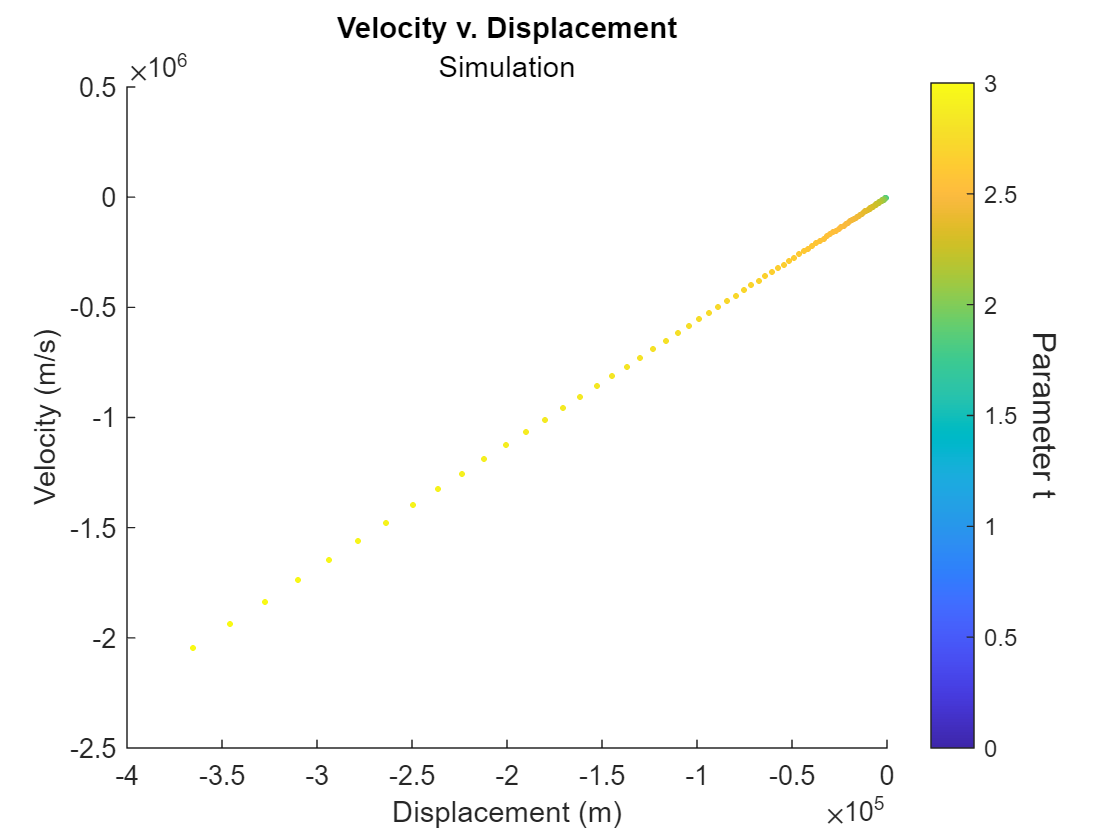

sr.plotXdX();

The default simulation does *not* include the use of LQR and consequently the pendulum is unstable. Enable LQR by setting its simulation parameter to `true`:

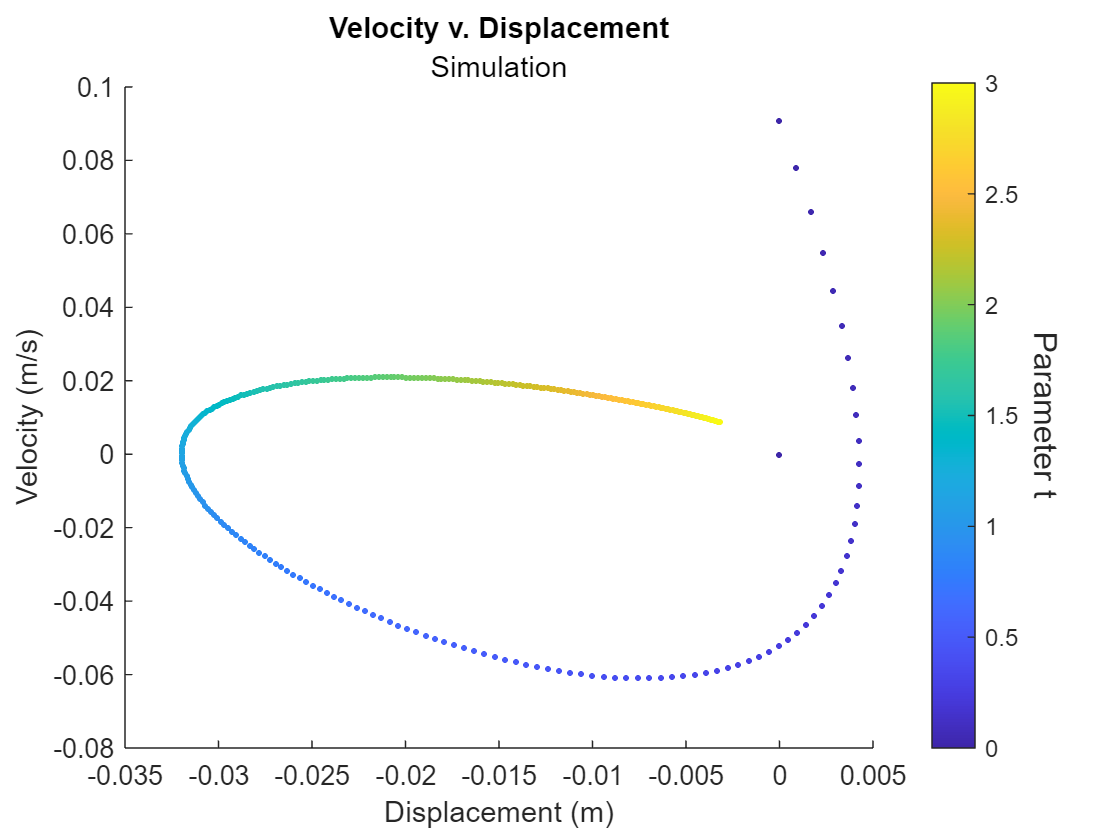

sr = IP.euler_method(V0, Force, lqr=true);
sr.plotXdX()

### Run an Experiment

An experiment is basically a comparison of two or more simulations. Below, we compare the effect of two supplied forces 5 and 0.25 N respectively. Note the use of the `description` argument to identify the simulation:

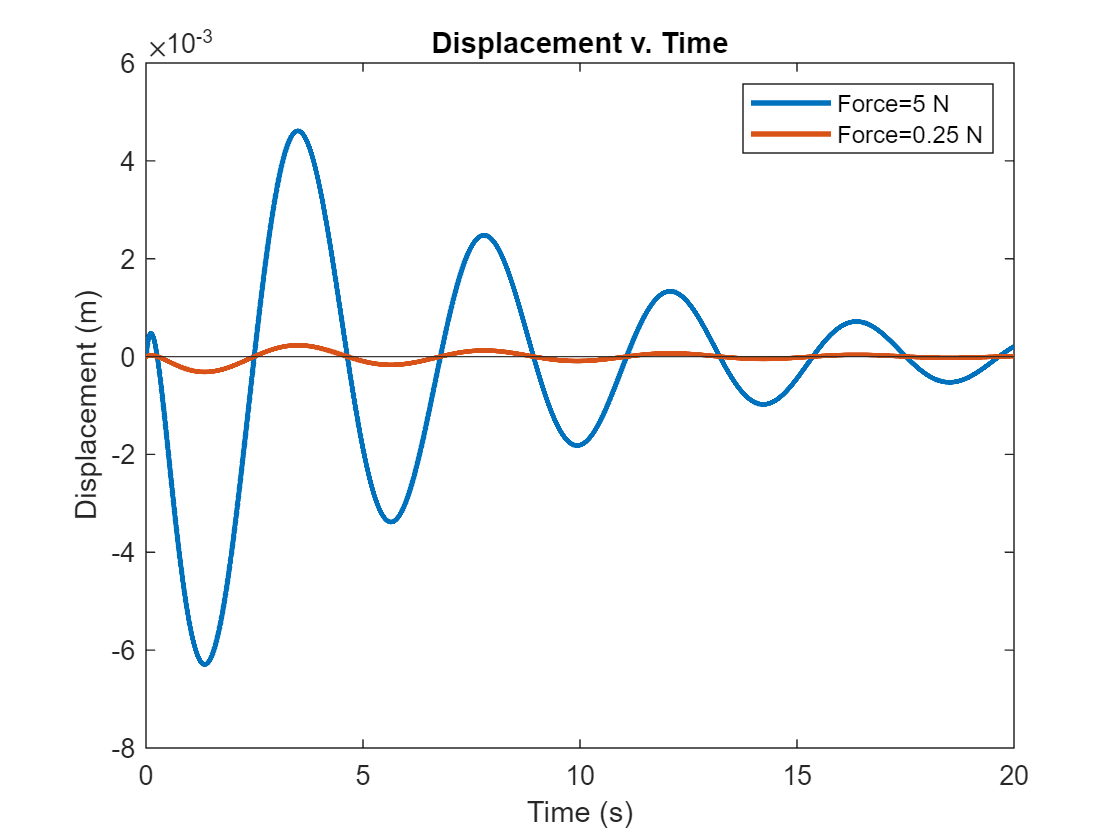

time_t = [0:0.001:20];

IP = InvertedPendulum();

V0 = [0;0; 0;0]; % Initial position

%non-default LQR 'Q' matrix that includes only X and phi:
Q = [1 0 0 0;
     0 0 0 0;
     0 0 1 0;
     0 0 0 0];

% create the inverted pendulum
IP = InvertedPendulum();

%simulate and plot the 5 Newton force
sr = IP.euler_method(V0, 5, time=time_t, lqr=true, ...
    Q=Q, description='Force=5 N');
sr.plotX;

%simulate and plot the 0.25 Newton force
sr2 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
     Q=Q, description='Force=0.25 N');
hold on
sr2.plotX
hold off

legend()